## symbolic expansion of D

clearvars; clc;
syms p0 Kd Kp Ki

% Konstanty z rovnice
a2 = 28.17;
a1 = 6915;
a0 = 1.023e5;
b1 = 2.917e4;
b0 = 2.917e5;

% D(s) = .
p1 = -6;
p2 = -16;
p3 = -120;

% Roznásobení a extrakce koeficientů
syms s
D_sym = expand((s - p1)*(s - p2)*(s - p3)*(s - p0));
coeffs_D = coeffs(D_sym, s, 'All');  % [d4 d3 d2 d1 d0]
d3 = simplify(coeffs_D(2));
d2 = simplify(coeffs_D(3));
d1 = simplify(coeffs_D(4));
d0 = simplify(coeffs_D(5));

% Rovnice podle metody A(s)*s + B(s)*R(s) = D(s)
eq1 = a2 + b1*Kd == d3;
eq2 = a1 + b1*Kp + b0*Kd == d2;
eq3 = a0 + b1*Ki + b0*Kp == d1;
eq4 = b0*Ki == d0;

% Vyřeš soustavu rovnic
sol = solve([eq1, eq2, eq3, eq4], [Kd, Kp, Ki, p0]);

% Výpis výsledků
disp('Řešení pro Kd, Kp, Ki, p_real:');

Řešení pro Kd, Kp, Ki, p_real:


disp(['Kd:     ', char(vpa(sol.Kd, 10))]);

Kd:     0.008785764744


disp(['Kp:     ', char(vpa(sol.Kp, 10))]);

Kp:     0.4623311622


disp(['Ki:     ', char(vpa(sol.Ki, 10))]);

Ki:     5.625754979


disp(['p0: ', char(vpa(sol.p0, 10))]);

p0: -142.4507576


## zjednodušení levé a pravé strany

% ============================================
% Symbolic simplification of both sides of
% A(s)*X(s) + B(s)*Y(s) = D(s)
% (corrected version: A is numerator, B is denominator)
% ============================================

clearvars; clc;
syms s Kd Kp Ki p0

% Corrected plant polynomials:
A = 2.917e4*s + 2.917e5;                             % numerator of plant
B = s^3 + 28.17*s^2 + 6915*s + 1.023e5;              % denominator of plant

% PID controller:
X = Kd*s^2 + Kp*s + Ki;   % numerator of controller
Y = s;                    % denominator of controller

% Left-hand side of Diophantine equation: A(s)*X(s) + B(s)*Y(s)
LHS = expand(A*X + B*Y);
LHS_collected = collect(LHS, s);

% Desired closed-loop polynomial:
D = expand((s + 6)*(s + 16)*(s + 120)*(s- p0));
RHS_collected = collect(D, s);

% Display both sides
disp('Left-hand side (LHS):');

Left-hand side (LHS):


pretty(LHS_collected)

 4   /            2817 \  3                                  2
s  + | 29170 Kd + ---- | s  + (291700 Kd + 29170 Kp + 6915) s  + (29170 Ki + 291700 Kp + 102300) s + 291700 Ki
     \             100 /



disp('Right-hand side (RHS):');

Right-hand side (RHS):


pretty(RHS_collected)

 4               3                    2
s  + (142 - p0) s  + (2736 - 142 p0) s  + (11520 - 2736 p0) s - 11520 p0



## plot step

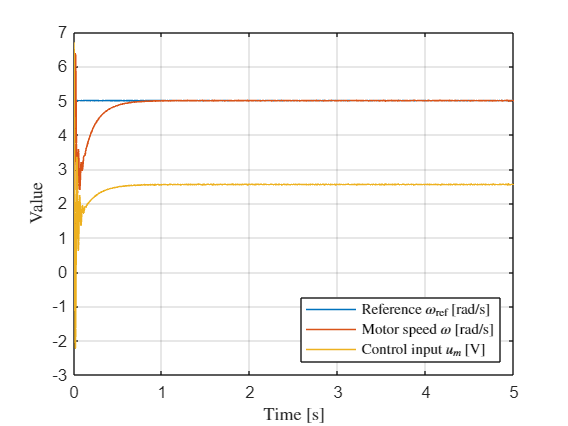

% Load the .mat file
load("polynomial_pid_step.mat");  % Assumes the timeseries is stored in variable 'ans'

% Extract timeseries data
omega         = ans.Data(:,1);  % Motor velocity [rad/s]
reference     = ans.Data(:,2);  % Reference signal [rad/s]
control_input = ans.Data(:,3);  % Controller output [V]

time = ans.Time;  % Time vector

% Create figure
figure;
plot(time, reference, 'LineWidth', 1); hold on;
plot(time, omega, 'LineWidth', 1);
plot(time, control_input, 'LineWidth', 1);

ylabel('Value', 'Interpreter', 'latex');
xlabel('Time [s]', 'Interpreter', 'latex');
title('', 'Interpreter', 'latex');
grid on;

legend({ ...
    'Reference $\omega_{\mathrm{ref}}$ [rad/s]', ...
    'Motor speed $\omega$ [rad/s]', ...
    'Control input $u_m$ [V]' ...
    }, 'Location', 'southeast', 'Interpreter', 'latex');

% Save as EPS
print('plots/polynomial_pid_step', '-depsc');

## disturbance plot

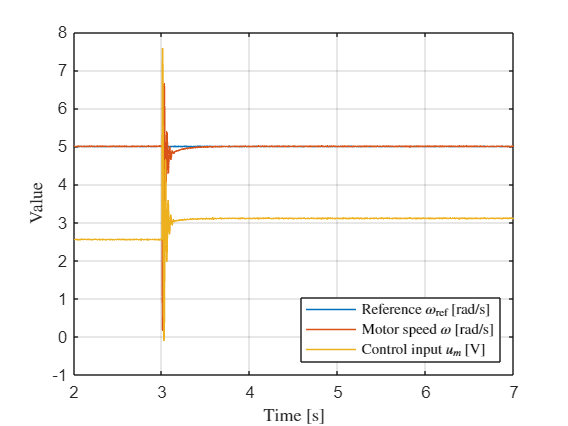

% Load the .mat file
load("polynomial_pid_step_disturbance.mat");  % timeseries stored as 'ans'

% Extract data
omega         = ans.Data(:,1);  % Motor velocity [rad/s]
reference     = ans.Data(:,2);  % Reference signal [rad/s]
control_input = ans.Data(:,3);  % Controller output [V]
time = ans.Time;

% Trim data starting from t >= 2 seconds
idx = time >= 2;
time = time(idx);
omega = omega(idx);
reference = reference(idx);
control_input = control_input(idx);

% Create figure
figure;
plot(time, reference, 'LineWidth', 1); hold on;
plot(time, omega, 'LineWidth', 1);
plot(time, control_input, 'LineWidth', 1);

ylabel('Value', 'Interpreter', 'latex');
xlabel('Time [s]', 'Interpreter', 'latex');
grid on;

legend({ ...
    'Reference $\omega_{\mathrm{ref}}$ [rad/s]', ...
    'Motor speed $\omega$ [rad/s]', ...
    'Control input $u_m$ [V]' ...
    }, 'Location', 'southeast', 'Interpreter', 'latex');

% Save as EPS
print('plots/polynomial_pid_step_disturbance', '-depsc');

## random hovno

% Define numerator and denominator
num = 1;
den = [1 0.2 1 0];  % s^3 + 0.2s^2 + s

% Create transfer function
G = tf(num, den);

sisotool(G)